close all;
clearvars;
clc;

addpath("./functions/");
ds_path = "./datasets/";

# Model Initialisation

% 20s pre-jump dataset is imported
data_tt = readtimetable(ds_path + "dataset_regular_20s.csv");

% Model parametres
features = {@(x) median(x, 1)};
feature_labels = ["median"];

slow_vars = ["prc_iron_feed", "prc_silica_feed", ...
                    "prc_iron_concentrate", "prc_silica_concentrate"];
input_vars = data_tt.Properties.VariableNames; % CHANGE THIS!!!
output_vars = "prc_silica_concentrate";
pred_horizon = 1; 


# Experimentation with different lags

component_counts = 1:10;
input_memory = 1:10;
% Initialize model struct
model = struct();
for m = input_memory
    [X_init, Y_init] = init_dataset(data_tt, input_vars, output_vars, ...
                                m, pred_horizon, features, feature_labels);
    variable_names = Var_name(X_init, Y_init, 10, 10);
    X_init = X_init(:, variable_names);
    train_indices = 1:round(height(X_init) * 0.70);
    test_indices = (length(train_indices) + 1):height(X_init);
    meanQ2_sum = zeros(size(component_counts));
    meanR2_sum = zeros(size(component_counts));

    for j = 1:numel(component_counts)
        % Center and scale the X-matrices
        X = zscore(X_init{train_indices,:});
        % Test
        Xt = zscore(X_init{test_indices,:});
        Xt(isnan(Xt)) = 0;

        % Center the Y-matrices
        Y = Y_init{train_indices, 1} - mean(Y_init{train_indices, 1});
        % Test
        Yt = Y_init{test_indices, 1} - mean(Y_init{train_indices, 1});

        % Computing PLS model
        [~, ~, ~, ~, model(m).ncomp(j).B, ...
            model(m).ncomp(j).MSE, ...
            model(m).ncomp(j).stats] = plsregress(X, Y, component_counts(j));

        % Calculate R2
        Yfit = [ones(size(X,1),1) X] * model(m).ncomp(j).B;
        TSSRes = sum((Y - mean(Y)).^2);
        RSSRes = sum((Y - Yfit).^2);
        model(m).ncomp(j).R2 = 1 - RSSRes / TSSRes;

        % Calculate Q2
        YfitT = [ones(size(Xt,1),1) Xt] * model(m).ncomp(j).B;
        PRESS = sum((Yt - YfitT).^2);
        model(m).ncomp(j).Q2 = 1 - PRESS / TSSRes;
    
        % Accumulate Q2 and R2 values
        meanQ2_sum(j) = model(m).ncomp(j).Q2;
        meanR2_sum(j) = model(m).ncomp(j).R2;

    end 
    % Calculate the mean Q2 and R2 for this value of m
    model(m).meanQ2 = mean(meanQ2_sum);
    model(m).meanR2 = mean(meanR2_sum);
end

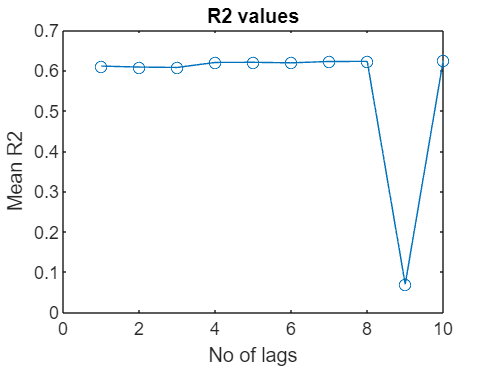

m = 1:10;  % Define the range of m

R2 = zeros(size(m));
Q2 = zeros(size(m));

for i = 1:length(m)
    R2(i) = model(m(i)).meanR2;
    Q2(i) = model(m(i)).meanQ2;
end

figure;
plot(m, R2, "-o");
ylabel("Mean R2");
xlabel("No of lags");
title("R2 values");

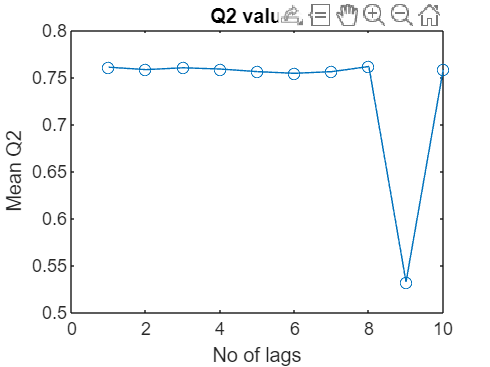


figure;
plot(m, Q2, "-o");
ylabel("Mean Q2");
xlabel("No of lags");
title("Q2 values");

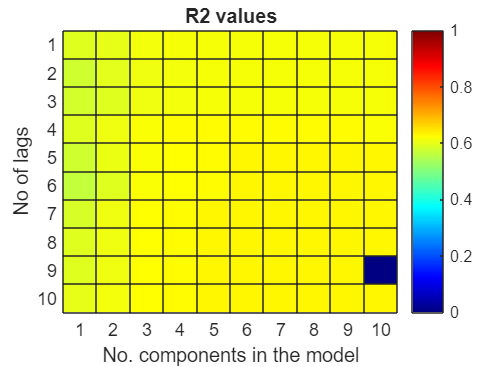

m = 1:10;

for i = 1:length(m)
    for j = 1:10
        R(i,j) = model(m(i)).ncomp(j).R2;
        Q(i,j) = model(m(i)).ncomp(j).Q2;
    end
end

figure;
yvalues = {'1', '2', '3', '4', '5', '6', '7', '8', '9', '10'};
xvalues = {'1', '2', '3', '4', '5', '6', '7', '8', '9', '10'};
hR2 = heatmap(xvalues, yvalues, R, 'ColorMethod', 'mean');
hR2.Colormap = jet; 
hR2.ColorLimits = [0, 1];
ylabel("No of lags");
xlabel("No. components in the model");
title("R2 values")

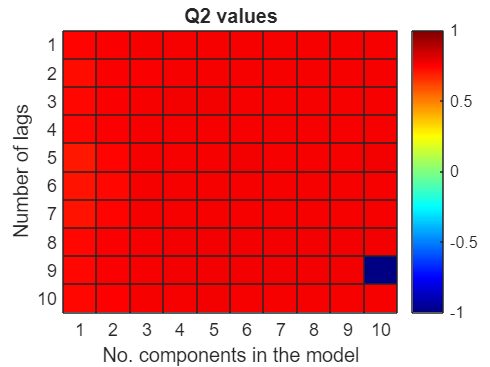


figure;
hQ2 = heatmap(xvalues, yvalues, Q, 'ColorMethod', 'mean');
hQ2.Colormap = jet; 
hQ2.ColorLimits = [-1, 1];  
ylabel("Number of lags");
xlabel("No. components in the model");
title("Q2 values");

close all;
clearvars;
clc;

addpath("./functions/");
ds_path = "./datasets/";

% 20s pre-jump dataset is imported
data_tt = readtimetable(ds_path + "dataset_regular_20s.csv");

% Model parametres
features = {@(x) median(x, 1), @(x) rms(x, 1)};
feature_labels = ["median", "rms"];

slow_vars = ["prc_iron_feed", "prc_silica_feed", ...
                    "prc_iron_concentrate", "prc_silica_concentrate"];
input_vars = data_tt.Properties.VariableNames; 
output_vars = "prc_silica_concentrate";
input_memory = 2; 
pred_horizon = 1; % Must be >=1 to respect causality

[X_init, Y_init] = init_dataset(data_tt, input_vars, output_vars, ...
                                input_memory, pred_horizon, features, feature_labels);

variable_names = X_init.Properties.VariableNames;

% Initialize model struct
variable_names = X_init.Properties.VariableNames;
component_counts = 10;
model = struct();
m = 10;
l = length(variable_names);
prev_mean_q2 = 0;
while m <= l
    train_indices = 1:round(height(X_init) * 0.70);
    test_indices = (length(train_indices) + 1):height(X_init);

    % Initialize variables to track the best PC and corresponding Q2
    best_pc = 0;
    best_q2 = -inf;
    meanQ2_sum = zeros(size(component_counts));
    meanR2_sum = zeros(size(component_counts));
    for j = 1:numel(component_counts)
        % Center and scale the X-matrices
        X = zscore(X_init{train_indices, 1:m});
        % Test
        Xt = zscore(X_init{test_indices, 1:m});
        Xt(isnan(Xt)) = 0;
        % Center the Y-matrices
        Y = Y_init{train_indices, 1} - mean(Y_init{train_indices, 1});
        % Test
        Yt = Y_init{test_indices, 1} - mean(Y_init{train_indices, 1});

        % Computing PLS model
        [~, ~, ~, ~, model(m).ncomp(j).B, ...
            model(m).ncomp(j).MSE, ...
            model(m).ncomp(j).stats] = plsregress(X, Y, component_counts(j));

        % Calculate R2
        Yfit = [ones(size(X,1),1) X] * model(m).ncomp(j).B;
        TSSRes = sum((Y - mean(Y)).^2);
        RSSRes = sum((Y - Yfit).^2);
        model(m).ncomp(j).R2 = 1 - RSSRes / TSSRes;

        % Calculate Q2
        YfitT = [ones(size(Xt,1),1) Xt] * model(m).ncomp(j).B;
        PRESS = sum((Yt - YfitT).^2);
        model(m).ncomp(j).Q2 = 1 - PRESS / TSSRes;
    
        % Accumulate Q2 and R2 values
        meanQ2_sum(j) = model(m).ncomp(j).Q2;
        meanR2_sum(j) = model(m).ncomp(j).R2;

        % Check if the current PC count yields the best Q2
        if model(m).ncomp(j).Q2 > best_q2
            best_pc = j;
            best_q2 = model(m).ncomp(j).Q2;
        end
    end 
    % Calculate the mean Q2 and R2 for this value of m
    model(m).meanQ2 = mean(meanQ2_sum);
    model(m).meanR2 = mean(meanR2_sum);

    if best_q2 <= prev_mean_q2;
        [~, minIdx] = min(abs(model(m).ncomp(best_pc).B));

        % Store the variable name to remove
        varImpToRemove = variable_names{minIdx};

        % Remove the variable with the minimum variable importance
        X_init.(varImpToRemove) = [];
        variable_names = X_init.Properties.VariableNames;
        l = length(variable_names);
    else
        prev_mean_q2 = best_q2;
        m = m + 1;
    end    
end

variable_names = X_init.Properties.VariableNames

variable_names = 1x22 cell array
    {'fc5_level_median_t-2'}    {'fc5_level_rms_t-2'}    {'fc6_air_flow_median_t-2'}    {'fc6_air_flow_rms_t-2'}    {'fc6_level_median_t-2'}    {'fc6_level_rms_t-2'}    {'fc7_air_flow_median_t-2'}    {'fc7_air_flow_rms_t-2'}    {'fc7_level_median_t-2'}    {'fc7_level_rms_t-2'}    {'ore_pulp_density_median_t-2'}    {'ore_pulp_density_rms_t-2'}    {'ore_pulp_flow_median_t-2'}    {'ore_pulp_flow_rms_t-2'}    {'ore_pulp_ph_median_t-2'}    {'ore_pulp_ph_rms_t-2'}    {'starch_flow_median_t-2'}    {'starch_flow_rms_t-2'}    {'prc_iron_concentrate_t-2'}    {'prc_iron_feed_t-2'}    {'prc_silica_concentrate_t-2'}    {'prc_silica_feed_t-2'}


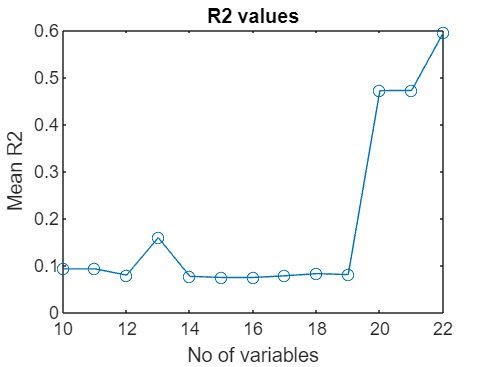

m = 10:length(variable_names); 

R2 = zeros(size(m));
Q2 = zeros(size(m));

for i = 1:length(m)
    R2(i) = model(m(i)).meanR2;
    Q2(i) = model(m(i)).meanQ2;
end

figure;
plot(m, R2, "-o");
ylabel("Mean R2");
xlabel("No of variables");
title("R2 values");

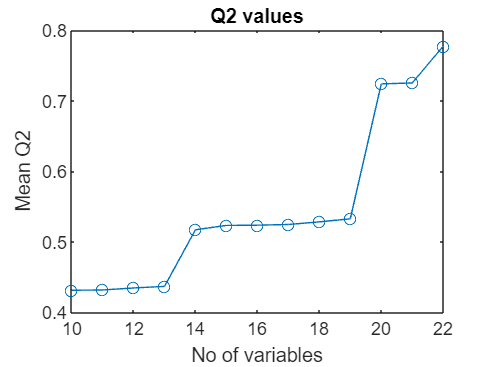


figure;
plot(m, Q2, "-o");
ylabel("Mean Q2");
xlabel("No of variables");
title("Q2 values");